# Miniprojekt 2 - Frekvensanalyse af målte vibrationssignaler

## Indledning

## Formål

Bliv fortrolig med diskret Fouriertransformation (DFT), og anvend denne til at analysere frekvensindholdet i forskellige signaler. Bliv fortrolig med Matlab til at håndtere og analysere digitale signaler.

### Loading af fil

Vi vil starte med at loade signalet ind i Matlab sammen med dens samplingfrekvens.

load("Opgave2_audiofil_1_1.mat"); % Medfølgende fil loades

### **A. Plot de første 5 sekunder og beskriv hvilke frekvenser som I forventer signalet indeholder ud fra det tidslige plot. Tidsskalaen skal være i sekunder og amplitudeskalaen i volt**

Først laves den korrekte skalering af amplituden, da 1 volt svarer til 100 enheder.

raw_input = raw_input.*0.01; % Medfølgende signal ændres til 1 volt skalering
fs % Sampelfrekvens

fs = 25600

Først beregnes sample periode tiden med formlen:


$$\mathrm{Ts}=\frac{1}{\mathrm{Fs}}$$


Nu da vi har loaded signalet ind, kan vi starte med at plotte de første fem sekunder.

Ts = 1/fs % Samples tid

Ts = 3.9063e-05

Nu laves en tidsakse på fem sekunder:

t = 0:Ts:5; % Tid

Et array over alle elementer laves:

n = 0:length(raw_input)-1; % Sample tæller

Signalet kan nu plottes:

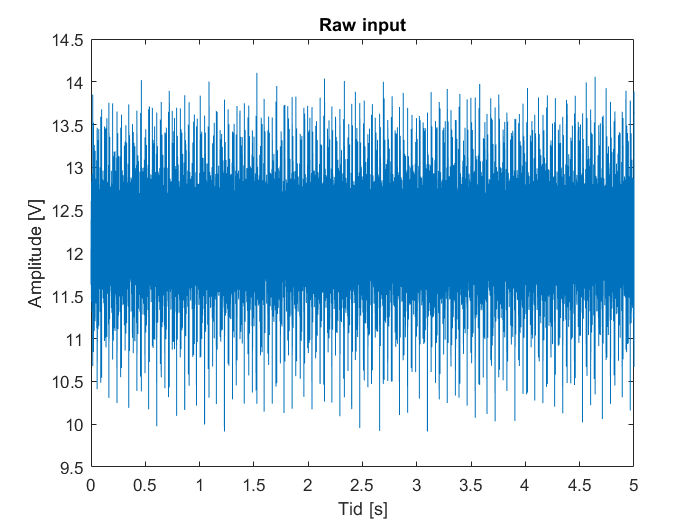

plot(n*Ts,raw_input); % raw_input plottet
title('Raw input'); % Titel
xlabel('Tid [s]'); ylabel('Amplitude [V]') % x- og y-label
xlim([0 5]) % x-akse spectrum

### **B. Beregn DC middelværdien, AC RMS-værdien, og energien for de første 5 sekunder af signalet.**

Til beregning af middelværdien, AC RMS-værdien, og energien bruges egne funktionsfiler som kan ses i bilag.

N = length(raw_input) % Antal samples

N = 262144

t_5 = t <= 5 ; % Tid til og med første 5 sekunder
raw_input5 = raw_input(t_5); % raw_input af de første 5 sekunder
mid = myMean(raw_input5) % Middelværdien

mid = 12.1765

raw_input5AC = raw_input5 - mid; % DC værdien fratrukket
rms = myRMS(raw_input5AC) % RMS-værdien

rms = 0.3278

energi = myEnergy(raw_input5AC) % Energien

energi = 1.3751e+04

### **C. Træk DC middelværdien fra tidssignalet. Den stammer fra forsyningsspændingen og bærer ingen signalinformation (i dette tilfælde).**

Da DC-værdien stammer fra forsyningsspændingen og ingen information har, trækkes den fra tidssignalet.

Vi har trukket DC middelværdien fra i forrige op opgave men gør det igen for opgavens skyld.

raw_input = raw_input-mid; % DC værdien fratrukket

Signalet uden DC-værdien plottes:

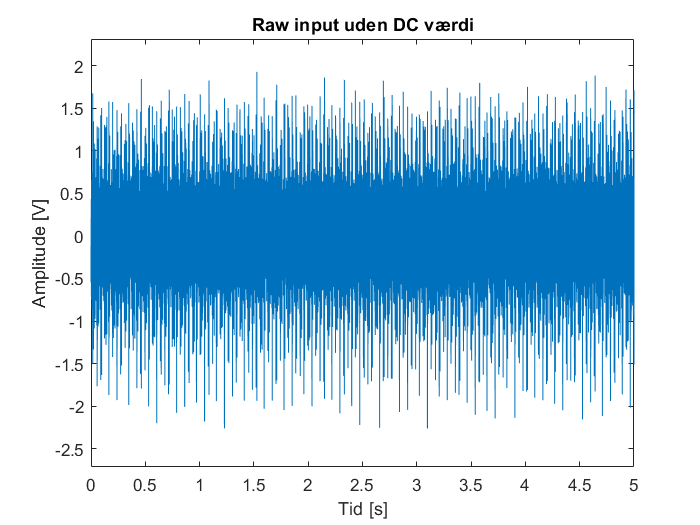

plot(n*Ts,raw_input); % raw_input plottet
title('Raw input uden DC værdi'); % Titel
xlabel('Tid [s]'); ylabel('Amplitude [V]'); % x- og y-label
xlim([0 5]); ylim([-2.7145 2.3125]); % x- og y-akse spectrum

### D. Lav frekvenstransformation på de første 5 sekunder af signalet og vis frekvensspektret.

Her plotter vi signal for de første 5 sekunder

N5 = length(raw_input5AC) % Antal samples for de første 5 sek uden DC

N5 = 128001

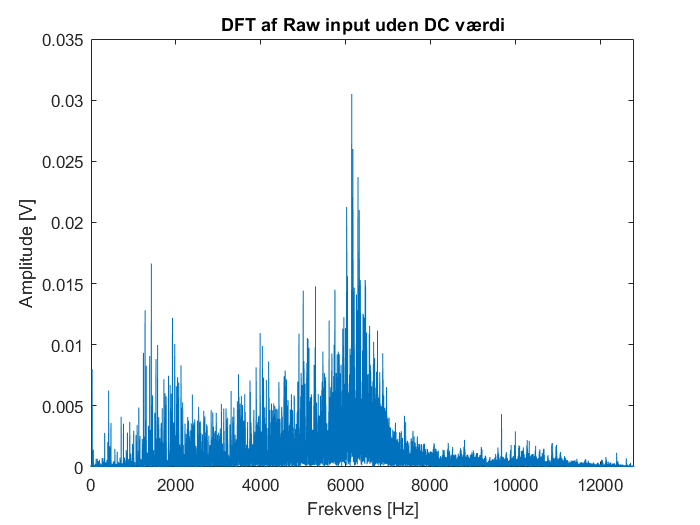

k = 0:N5-1; % Frekvens pins
DFT = fft(raw_input5AC,N5); % DFT
DFT = abs(DFT)*2/N5; % Op til nyquist
f5 = k*fs/N5; % Frekvensakse fem sekunder
plot(f5(floor(1:end/2)), DFT(floor(1:end/2))); % Plot af DFT 
title('DFT af Raw input uden DC værdi'); % Titel
xlabel('Frekvens [Hz]'); ylabel('Amplitude [V]'); % x- og y-label
xlim([0,fs/2]); % x-akse spectrum

### E. Vis spektret både med logaritmisk og lineær frekvensakse (begge i Hz), samt størrelsen både i dB (i forhold til 1 volt) og i lineært mål (volt eller millivolt).

Her opstiller vi 4 plots med forskellige akser for at vise forskellen på henholdsvis lineær og logariskmiske akser.

Det lineær plot plottes:

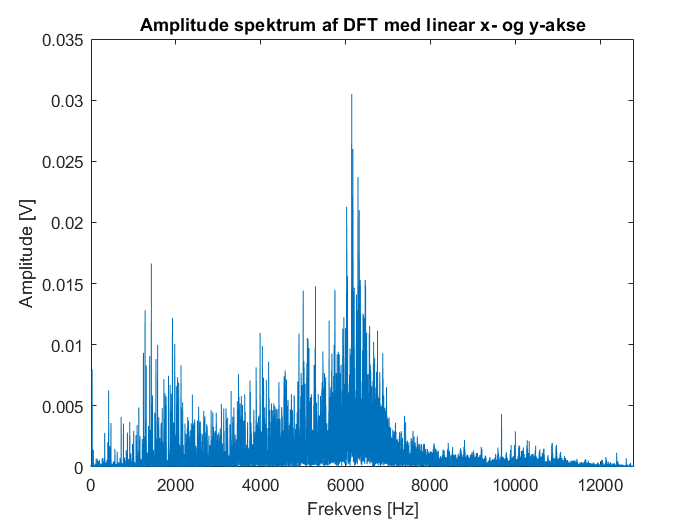

plot(f5(floor(1:end/2)), DFT(floor(1:end/2))); % Plot af DFT med linear x- og y-akse
title('Amplitude spektrum af DFT med linear x- og y-akse'); % Titel
xlabel('Frekvens [Hz]'); ylabel('Amplitude [V]'); % x- og y-label
xlim([0,fs/2]); % x-akse spectrum

Nu plottes der med logaritmisk frekvensakse og lineær amplitude akse:

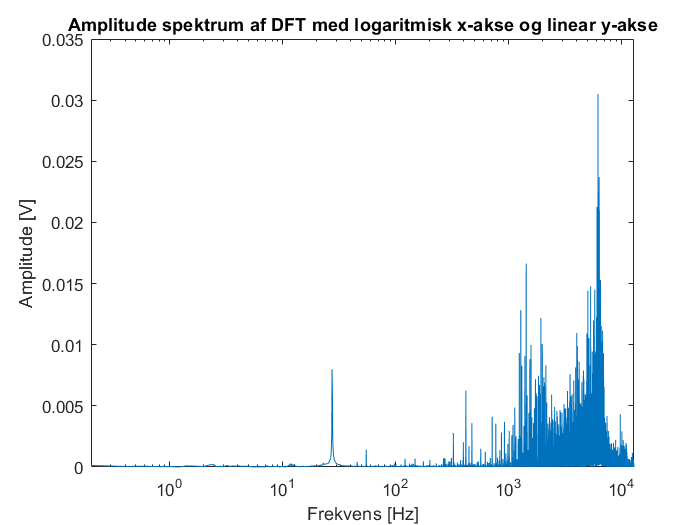

semilogx(f5(floor(1:end/2)), DFT(floor(1:end/2))); % Plot af DFT med logaritmisk x-akse og linear y-akse
xlim([0 length(k)/2]); % x-akse spectrum
title('Amplitude spektrum af DFT med logaritmisk x-akse og linear y-akse'); % Titel
xlabel('Frekvens [Hz]'); ylabel('Amplitude [V]'); % x- og y-label
xlim([0,fs/2]); % x-akse spectrum

Der laves nu et lineær frekvensakse plot med en amplitude akse i dB.

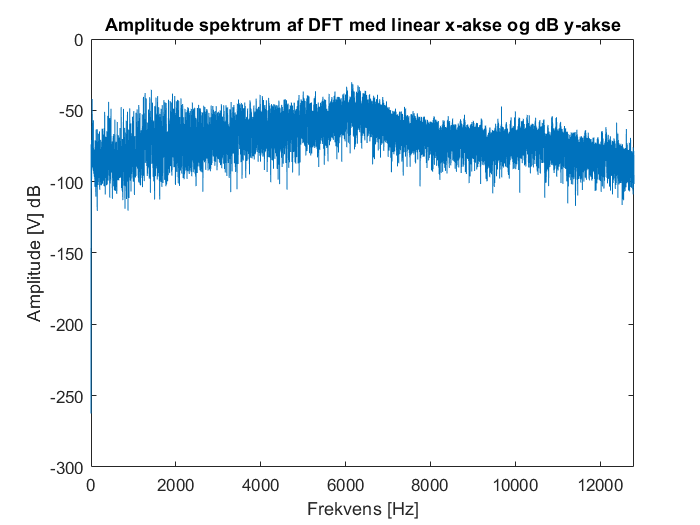

plot(f5(floor(1:end/2)), 20*log10(DFT(floor(1:end/2)))); % Plot af DFT med linear x-akse og dB y-akse
title('Amplitude spektrum af DFT med linear x-akse og dB y-akse'); % Titel
xlabel('Frekvens [Hz]'); ylabel('Amplitude [V] dB'); % x- og y-label
xlim([0,fs/2]); % x-akse spectrum

Der laves nu et logaritmisk frekvensakse plot med amplitude akse i dB.

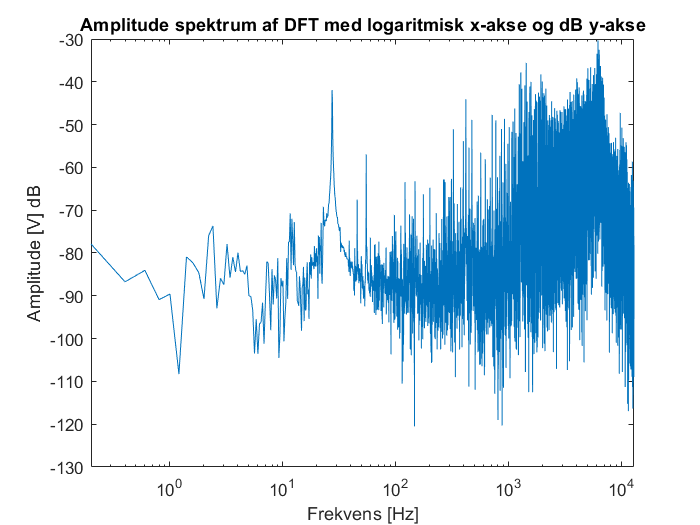

semilogx(f5(floor(1:end/2)), 20*log10(DFT(floor(1:end/2)))); % Plot af DFT med logaritmisk x-akse og dB y-akse
title('Amplitude spektrum af DFT med logaritmisk x-akse og dB y-akse'); % Titel
xlabel('Frekvens [Hz]'); ylabel('Amplitude [V] dB'); % x- og y-label
xlim([0,fs/2]); % x-akse spectrum

### F. Diskutér, hvornår man bør benytte hvilken skala.

x-akse:

Logaristmisk frekvensakser bør benyttes ved skævhed i retning af store værdier, det vil sige i tilfælde, hvor et eller flere punkter er meget større end størstedelen af dataene.  

Lineær frekvensakser bør benyttes ved et mindre antal samlet frekvenser fx 100 til 200 Hz, hvor der ikke er et så stort spring fra den mindste frekvens til den største frekvens.

Logaristmisk frekvensakser bør derfor bruges fx hvis man ser på et frekvensspectrum fra 20 til 20kHz, hvor man ikke ville kunne se de lave frekvenser på en lineær frekvensakse, fordi aksel afstanden er lige store. Hvorimod ved en logaristmisk frekvensakse vil den være opdel i fx 1, 10, 100, 1.000 , 10.000, hvilket giver et meget bedre overblik of et frekvens forløb.

y-akse:

Decibel amplitude akse er også en logarsitmisk akse, og bør benyttes ved de samme betingelser som den logaristmiske frekvensakse, det vil sige i tilfælde, hvor et eller flere punkter er meget større end størstedelen af dataene. Et eksempel kunne være at se på et spetrum som beskriver et lavpass- og højpass filter respons. Her ville man ikke kunne se responset for lavpass filteret hvis man brugte en lineær akse.

Lineær amplitude akser bør benyttes ved et mindre antal samlet værdier, hvor der ikke er et så stort spring fra den mindste værdi til den største værdi.

### G. Hvad er den dominerende frekvens, og passer den med det forventede?

Her vil vi finde maksværdierne i signalet og bestemme den dominerende frekvens.

[max_amplitude,max_frekvens] = max(DFT(floor(1:end/2))) % Maks værdier for amplitude og frekvens

max_amplitude = 0.0305

max_frekvens = 30735

Nu ved vi hvilken sample den dominerende frekvens er på, hvor den nu kan omregnes:

max_frekvens = round(f5(max_frekvens)) % Den dominerende frekvens

max_frekvens = 6147

Dermed er den dominerende frekvens fundet.

### H. Bestem lavfrekvent energi Elow (< 1000 Hz) og højfrekvent energi Ehigh (≥ 1000 Hz) for signalet. DC-værdien skal ikke tages med i disse beregninger.

Her vil vi bestemme energien i henholdsvis lavfrekvens- og højfrekvensområdet

raw_input5AC; % De første 5 sekunder af signalet uden DC
f5; % Frekvensen af de første 5 sekunder
f0 = 0; % Frekvenser fra 0 Hz
f1 = 1000; % Frekvenser til eller fra 1 kHz
f2 = 100000; % Frekvenser til 100 kHz

partLowRange = abs(f5)>f0&abs(f5)<f1; % lavfrekvenerne
partHighRange = abs(f5)>f1&abs(f5)<f2; % højfrekvenerne

Fpart_low = f5(partLowRange); % Frekvensspektret af de lave frekvenser
raw_input5AC_low = raw_input5AC(partLowRange); % 5 sekunders signalet med de lave frekvenser

Fpart_high = f5(partHighRange); % Frekvensspektret af de høje frekvenser
raw_input5AC_high = raw_input5AC(partHighRange); % 5 sekunders signalet med de høje frekvenser

E_low = myEnergy(raw_input5AC_low) % Energien under 1000 Hz

E_low = 519.4604

E_high = myEnergy(raw_input5AC_high) % Energien over 1000 Hz

E_high = 1.3231e+04

### I. Bestem energiforholdet Elow/Ehigh. Hvad betyder dette forhold?

Her bestemmes energiforholdet mellem det lavfrekvens- og højfrekvensområde.

E_forhold = E_low/E_high % Energiforholdet af E_low/E_high

E_forhold = 0.0393

E_forhold_pro = E_low/E_high*100 % Energiforholdet af E_low/E_high i procent

E_forhold_pro = 3.9260

E_f = 100/E_forhold_pro % E_low er cirka 25 gange mindre end E_high

E_f = 25.4713

Forholdet beskriver at e_low er cirka 25 gange mindre end E_high, hvilket betyder at amplituden er meget større ved de høje frekvenser, hvilket også ses på de 4 plot i opgave E.

### J. Gang et Hanning-vindue på signalet og lav igen frekvenstransformation. Vis spektret. Gør vinduet nogen forskel i dette tilfælde? Hvorfor/hvorfor ikke?

Her tilføjet vi signalet med et Hanning-vindue for at se forskellen.

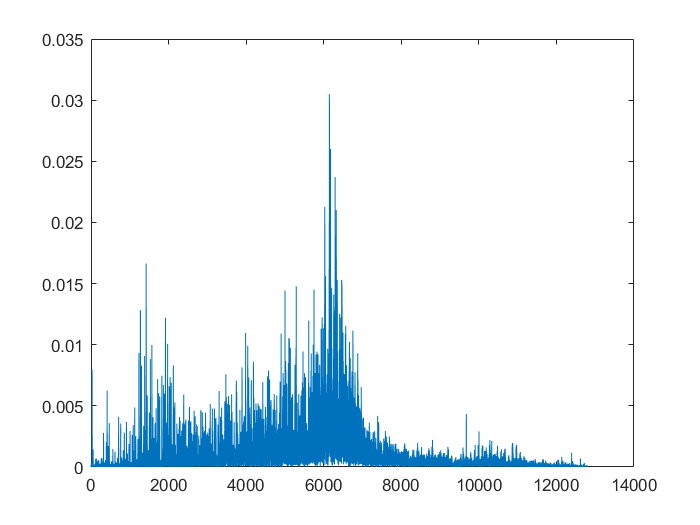

plot(f5(floor(1:end/2)), DFT(floor(1:end/2))) % Plot af DFT

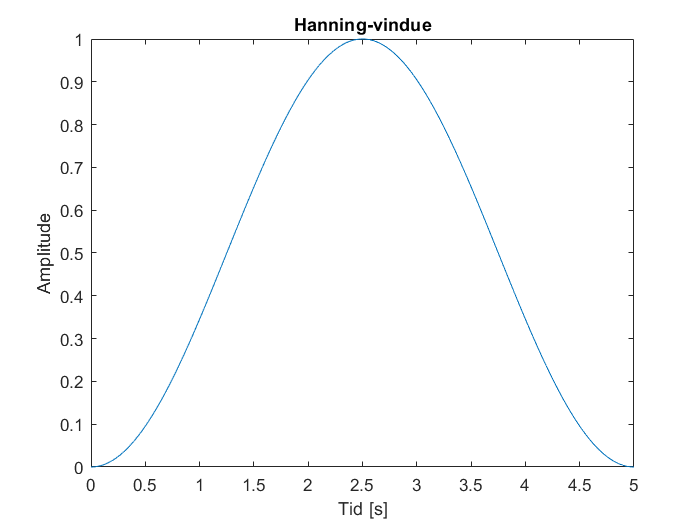

window = win(N5,'hanning'); % Hanning-vindue
n_hanning = 0:N5-1; % Sample tæller for de første 5 sekunder
plot(n_hanning*Ts, window); % Plot af Hanning-vindue
title('Hanning-vindue'); % Titel
xlabel('Tid [s]'); ylabel('Amplitude'); % x- og y-label

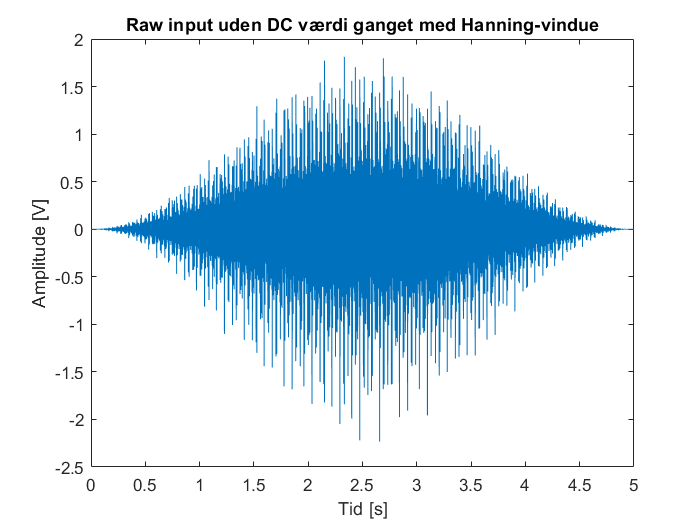

raw_win = raw_input5AC.*window; % raw_input af de første 5 sekunder uden DC ganget med Hanning-vindue
plot(n_hanning*Ts, raw_win); % Plot af raw_input første 5 sekunder uden DC ganget med Hanning-vindue
title('Raw input uden DC værdi ganget med Hanning-vindue'); % Titel
xlabel('Tid [s]'); ylabel('Amplitude [V]'); % x- og y-label

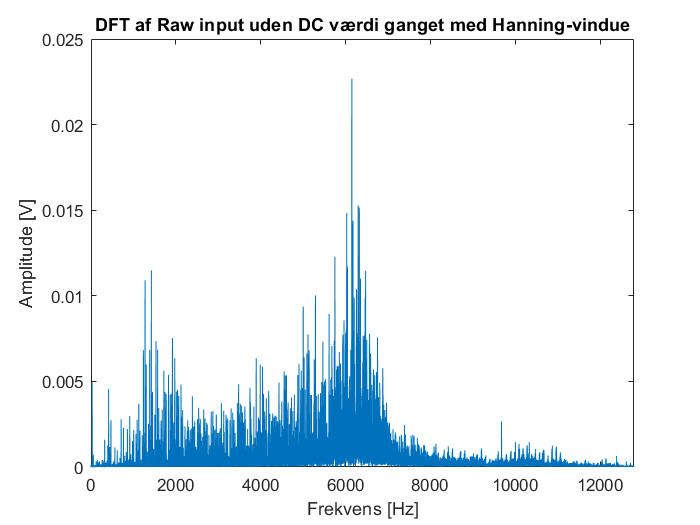

DFT_org_win = fft(raw_win); % DFT ganget med Hanning-vindue
plot(f5, abs(DFT_org_win)*2/N5); % Plot af Original DFT ganget med Hanning-vindue
title('DFT af Raw input uden DC værdi ganget med Hanning-vindue'); % Titel
xlabel('Frekvens [Hz]'); ylabel('Amplitude [V]'); % x- og y-label
xlim([0,fs/2]); % x-akse spectrum

Her ses Hanning-vinduet ganget med signalet på de første 5 sekunder uden DC.

Det ses ved plottet ovenfor, at amplituden er minimeret ved DFT'en ganget med Hanning-vinduet. Vi får dæmpet de lave energier, men også den dominerende frekvens. Man kunne også korrigere for dette, men så vil vi få det oprindelige plot, hvilket ikke giver mening.

### K. Beregn igen AC RMS-værdien, og energien for de første 5 sekunder af signalet, nu med Hanning-vinduet ganget på. Hvad gør Hanning vinduet ved disse værdier?

Her finder vi AC RMS-værdien, og energien for signalet med Hanning-vinduet og sammenligner værdierne for tidligere uden Hanning-vinduet.

rmsHann = myRMS(raw_win) % RMS-værdien med Hanning-vinduet

rmsHann = 0.1996

energiHann = myEnergy(raw_win) % Energien med Hanning-vinduet

energiHann = 5.1017e+03

rms_forskel = rmsHann/rms*100 % RMS-forholdet i procent

rms_forskel = 60.9105

energi_forskel = energiHann/energi*100 % Energi-forholdet i procent

energi_forskel = 37.1009

Efter at Hanning-vinduet er ganget på raw_input signalet, så er RMS-værdien dæmpet cirka 60% og energien er dæmpet cirka 37%.

### L. Lav en udglatning/smoothing af signalet i frekvensdomænet og vis det resulterende spektrum på et plot. Diskuter hvornår det bør bruges, og hvad det gør ved den dominerende frekvens.

For at lave en udglatning, anvendes funktionen smoothMag som tage n forgående og n efterfølgende og finder gennemsnittet. 

Nu plottes det udglattet signal af amplitude spektrummet, med lineære akser.

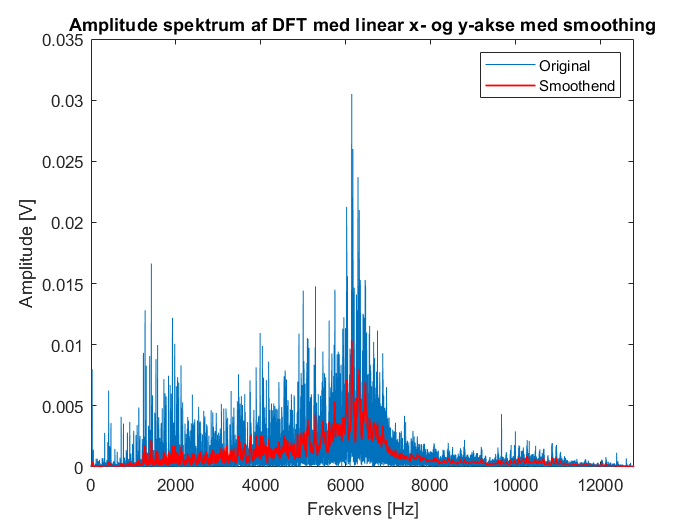

plot(f5(floor(1:end/2)), DFT(floor(1:end/2))); % Plot af DFT med linear x- og y-akse med smoothing
title('Amplitude spektrum af DFT med linear x- og y-akse med smoothing'); % Titel
xlabel('Frekvens [Hz]'); ylabel('Amplitude [V]'); % x- og y-label
xlim([0,fs/2]); % x-akse spectrum
hold on
smoothened=smoothMag(DFT(floor(1:end/2)),99); % Smoothing
plot(f5(floor(1:end/2)),smoothened,'r','LineWidth',1); % Plot af smoothing
legend('Original','Smoothend'); % Benævnelser
hold off

Nu plottes det samme udglattet signal med en amplitude akse i dB.

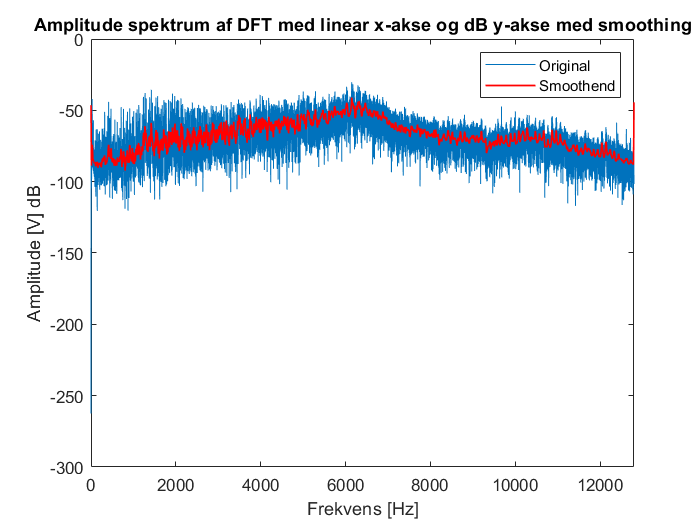

plot(f5(floor(1:end/2)), 20*log10(DFT(floor(1:end/2)))); % Plot af DFT med linear x-akse og dB y-akse med smoothing
title('Amplitude spektrum af DFT med linear x-akse og dB y-akse med smoothing'); % Titel
xlabel('Frekvens [Hz]'); ylabel('Amplitude [V] dB'); % x- og y-label
xlim([0,fs/2]); % x-akse spectrum
hold on
smoothened=smoothMag(20*log10(DFT(floor(1:end/2))),99); % Smoothing
plot(f5(floor(1:end/2)),smoothened,'r','LineWidth',1); % Plot af smoothing
legend('Original','Smoothend'); % Benævnelser
hold off

Det ses tydeligt at amplituden af den dominerende frekvens bliver udglattet, dæmpet. Derfor vil det ikke være ideelt at bruge funktionen til det første plot. Det kan dog anvendes i det andet plot, da der ikke er så store udsving generelt set.